clear all, close all, clc

############### ############### ############### ###############

## HW05-1

Let's find out the no. of O-atoms in water

Na = 6.02e23;           % Avogadro's no.; #/mol
A_o = 16;               % for oxygen; g/mol
A_w = 18;               % mass no., water; g/mol

Now, let's do the follows-

$N_m =\frac{f_i }{A_w }N_a$    Here, $N_m =$ specific no. of atoms [#/g]

f_o = 1;                % no. of O, in water
Nm_o = f_o/A_w *Na      % O-atoms, in water; #/g

Nm_o = 3.3444e+22

Then, we know, energy absorbed by a species-


$$\epsilon =\frac{2\textrm{EA}}{{\left(A+1\right)}^2 }$$


E = 0.1;                % nu' energy; MeV
  J_MeV = 1.602e-13;    % J/MeV
E = E *J_MeV;           % J
e_o = 2*E*A_o /(A_o +1)^2    % energy absorbed by O; J

e_o = 1.7738e-15

Similarly, let's calculate for H-atoms in water

A_h = 1;                % for hydrogen; g/mol
f_h = 2;                % no. of H, in water
Nm_h = f_h/A_w *Na      % H-atoms, in water; #/g

Nm_h = 6.6889e+22

Then we have,

e_h = 2*E*A_h /(A_h +1)^2    % energy absorbed by H; J

e_h = 8.0100e-15

Now, from Textbook AC-TC.1

sg_s_o = 4.03;          % elastic scattering CS, O; b
sg_s_o = sg_s_o*1e-24;  % cm^2
sg_s_h = 30.5;          % elastic scattering CS, H; b
sg_s_h = sg_s_h*1e-24;  % cm^2

Now, we know, the Kerma response function-


$$R=\sum_{\;} \frac{N_i \left(r\right)}{\rho_i \left(r\right)}\;\sum_{\;} \sigma_{\textrm{ij}} \left(E\right)\;\epsilon_{\textrm{ij}} \left(E\right)$$


Or, $R=\sum_{\;} N_{\textrm{mi}} \left(r\right)\;\sum_{\;} \sigma_{\textrm{ij}} \left(E\right)\;\epsilon_{\textrm{ij}} \left(E\right)$

Here, we have-

R_k = (Nm_h + Nm_o) *(e_o *sg_s_o + e_h *sg_s_h)  % J.cm^2/gm

R_k = 2.5229e-14

R_k = R_k /1e-3         % J.cm^2/kg, Gy.cm^2

R_k = 2.5229e-11

(Ans)

Now, let's verify from the Appendix at D8, for similar neutron energy, 

R_k = 7.49e-12            % Gy.cm^2

R_k = 7.4900e-12

So, the two values are kind of similar-/

############### ############### ############### ###############

## HW05-2

Given, the tissue composition,

f_o = 0.762;            % fraction of O in tissue
f_c = 0.111;            % ... of C
f_h = 0.101;            % ... of H
f_n = 0.026;            % ... of N

Again, we have the followings-

Na = 6.02e23;           % Avogadro's no.; #/mol
A_o = 16;               % mass no., O; g/mol
A_h = 1;                % mass no., H; g/mol
A_c = 12;               % mass no., C; g/mol
A_n = 14;               % mass no., N; g/mol

Now, let's find the specific no. nuclides in tissue for individual species

Nm_o = f_o/A_o *Na       % specific no. of O in tissue; #/gm

Nm_o = 2.8670e+22

Nm_h = f_h/A_h *Na       % ...of H; #/gm

Nm_h = 6.0802e+22

Nm_c = f_c/A_c *Na       % ...of C; #/gm

Nm_c = 5.5685e+21

Nm_n = f_n/A_n *Na       % ...of N; #/gm

Nm_n = 1.1180e+21

Now, we know, the scattering CS are-

sg_s_h = 4.3*1e-24;     % scattering CS for H; cm^2
sg_s_o = 8.0*1e-24;     % scattering CS for O; cm^2
sg_s_c = 2.6*1e-24;     % scattering CS for C; cm^2
sg_s_n = 2.0*1e-24;     % scattering CS for N; cm^2

Let's find the absorbed energy for each species-

E = 1.0;                % nu' energy; MeV
  J_MeV = 1.602e-13;    % J/MeV
E = E *J_MeV;           % J

Now, we have-


$$\epsilon =\frac{2\textrm{EA}}{{\left(A+1\right)}^2 }$$


e_h = 2*E*A_h /(A_h +1)^2    % absorbed E, H; J

e_h = 8.0100e-14

e_o = 2*E*A_o /(A_o +1)^2    % absorbed E, O; J

e_o = 1.7738e-14

e_c = 2*E*A_c /(A_c +1)^2    % absorbed E, C; J

e_c = 2.2750e-14

e_n = 2*E*A_n /(A_n +1)^2    % absorbed E, N; J

e_n = 1.9936e-14

Now, let's do this


$$R=\sum_{\;} N_{\textrm{mi}} \left(r\right)\;\sum_{\;} \sigma_{\textrm{ij}} \left(E\right)\;\epsilon_{\textrm{ij}} \left(E\right)$$


Here, we go-

Nm_i = [Nm_h, Nm_o, Nm_c, Nm_n];    % #/gm
Nm_iS = sum(Nm_i)                   % summing all; #/gm

Nm_iS = 9.6159e+22

And then-

sg_s_i = [sg_s_h, sg_s_o, sg_s_c, sg_s_n]; % cm^2
e_i = [e_h, e_o, e_c, e_n];         % J

sg_e_i = sg_s_i .*e_i;              % taking product
sg_e_iS = sum(sg_e_i)               % summing all; J.cm^2

sg_e_iS = 5.8536e-37

So, the kerma response function

R_k = Nm_iS * (sg_e_iS)             % J.cm^2/gm

R_k = 5.6287e-14

R_k = R_k/1e-3                      % Gy.cm^2

R_k = 5.6287e-11

Now, given

phi = 1e13;                 % fluence; #/cm^2
K = R_k *phi                % kerma; Gy

K = 562.8749

(Ans)

Now, let's look into Textbook AD-TD.8

R_k =  2.53e-11;            % Gy.cm^2

Therefrom-

K = R_k*phi                 % kerma; Gy

K = 253

So, we see, there are some discrepancies, and the value found from the table nearly halves.

############### ############### ############### ###############

## HW05-3

### (a)

Given, the following table, with gap index (in red)

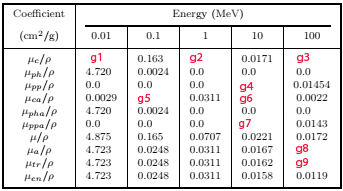

Let's use the value $\rho =1\;\frac{\textrm{gm}}{{\textrm{cm}}^3 }$, then the following array ensues-

MeV =    [0.01,     0.1,        1.0,        10,         100     ];   
mu_c =   [nan,      0.163,      nan,        0.0171,     nan     ];
mu_ph =  [4.72,     0.0024,     0.0,        0.0,        0.0     ];
mu_pp =  [0.0,      0.0,        0.0,        nan,        0.01454 ];
mu_ca =  [0.0029,   nan,        0.0311,     nan,        0.0022  ];
mu_pha = [4.72      0.0024,     0.0         0.0         0.0     ];
mu_ppa = [0.0,      0.0,        0.0,        nan,        0.0143  ];
mu =     [4.875,    0.165,      0.0707,     0.0221,     0.0172  ];
mu_a =   [4.723,    0.0248,     0.0311,     0.0167,     nan     ];
mu_tr =  [4.723,    0.0248,     0.0311,     0.0162,     nan     ];
mu_en =  [4.723,    0.0248,     0.0311,     0.0158,     0.0119  ];

Now, let's 1-by-1, fill teh gaps-

we know: $\mu =\mu_c +\mu_{ph} +\mu_{pp}$. So-

mu_c(1) = mu(1) - ( mu_ph(1) + mu_pp(1));
mu_c(3) = mu(3) - ( mu_ph(3) + mu_pp(3));
mu_c(5) = mu(5) - ( mu_ph(5) + mu_pp(5));
g1 = mu_c(1)         % cm^2/g

g1 = 0.1550

g2 = mu_c(3)         % cm^2/g

g2 = 0.0707

g3 = mu_c(5)         % cm^2/g

g3 = 0.0027

And then,

mu_pp(4) = mu(4) - ( mu_ph(4) + mu_c(4));
g4 = mu_pp(4)       % cm^2/g

g4 = 0.0050

Now, we know the follows-

$f_c =\frac{\mu_a -\left(\mu_{\textrm{ph}} +\mu_{\textrm{pp}} \right)}{\mu_c }$;    $\mu_{\textrm{ca}} =f_c \;\mu_c$

fc(2) = ( mu_a(2) - ( mu_ph(2) + mu_pp(2)) )/mu_c(2);
fc(4) = ( mu_a(4) - ( mu_ph(4) + mu_pp(4)) )/mu_c(4);
mu_ca(2) = fc(2)*mu_c(2);
mu_ca(4) = fc(4)*mu_c(4);
g5 = mu_ca(2)       % cm^2/g

g5 = 0.0224

g6 = mu_ca(4)       % cm^2/g

g6 = 0.0117

Then again, we know-

$\mu_{\textrm{tr}} =\mu_c f_c +\mu_{\textrm{ppa}} +\mu_{\textrm{pha}}$; so-

mu_ppa(4) = mu_tr(4) - ( mu_c(4)*fc(4) + mu_pha(4) );
g7 = mu_ppa(4)      % cm^2/g

g7 = 0.0045

Now, we know again-


$$\mu_a =\mu -\left(1-f_c \right)\mu_c$$


fc(5) = mu_ca(5)/mu_c(5);
mu_a(5) = mu(5)-(1-fc(5))*mu_c(5);
g8 = mu_a(5)        % cm^2/g

g8 = 0.0167

Lastly, we have-

$\mu_{\textrm{tr}} =\mu_c f_c +\mu_{\textrm{ppa}} +\mu_{\textrm{pha}}$; so-

mu_tr(5) = fc(5) *mu_c(5) + mu_ppa(5) + mu_pha(5);
g9 = mu_tr(5)       % cm^2/g

g9 = 0.0165

So, we have the following matrix again-

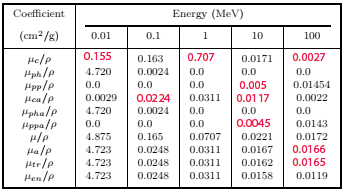

### (b)

Here, to prove-


$$\frac{\mu_{\textrm{en}} }{\rho \;}<\frac{\mu_{\textrm{tr}} }{\rho \;}<\frac{\mu_a }{\rho \;}$$


Now, we know,


$$\mu_{\textrm{en}} =\left(1-G\right)\;\mu_{\textrm{tr}}$$


    Here, 0<G <1; so, 0< (1 - G) < 1

    Henece,  $\mu_{\textrm{en}} <\mu_{\textrm{tr}}$

and, then we know the follows-


$$\mu_{\textrm{tr}} =\mu_{\textrm{tr}}^{\prime } -\left({1-f}_{\textrm{ph}} \right)\mu_{\textrm{ph}}$$



$$\mu_{\textrm{tr}}^{\prime } =\mu_a -\left({1-f}_{\textrm{pp}} \right)\mu_{\textrm{pp}}$$


So, analyzing the above, we get


$$\mu_{\textrm{tr}} <{\mu_{\textrm{tr}} }^{\prime } <\mu_a$$
 

So, combining  these, we can say-


$$\mu_{\textrm{en}} <\mu_{\textrm{tr}} <\mu_a$$
 

As the value $\rho \;$is positive, this implies-


$$\frac{\mu_{\textrm{en}} }{\rho \;}<\frac{\mu_{\textrm{tr}} }{\rho \;}<\frac{\mu_a }{\rho \;}$$


    (explained)

############### ############### ############### ###############

## HW05-4

### (a)

Given

$\dot{X} =\frac{6\textrm{CEN}}{r^2 }$ Here, C is in Ci, E in MeV,  r is in feet, N is branching

Here we know,

1 Ci = 3.7e(10) Bq

1 ft = 0.305 m

Now, we have


$$\dot{X} =6\frac{\textrm{CEN}}{r^2 }=6\frac{\left(3\ldotp 7\times {10}^{10} \right)\textrm{CEN}}{{\left(0\ldotp 305r\right)}^2 }$$



$$\dot{X} =2\ldotp 387\times {10}^{12} \frac{\textrm{CEN}}{r^2 }$$


    (Ans)

### (b)

Let assume-

C = 1;              % activity; Ci
r = 1;              % distance; ft
N = 1;              % photon branching
E = 1;              % photon energy; MeV

Now, we have this equation,


$$\dot{X} =6\frac{\textrm{CEN}}{r^2 }$$


which can be rearranged as-


$$\frac{\dot{X} r^2 }{\textrm{CEN}}=6=\textrm{Cs}$$


Let the constant value is Cs. so, we have for unit exposure-

x_dt = 6;           % unit exposure, R.h^-1

Then, the value of constant for this value of exposure would be-

Cs = x_dt*r^2 /(C*E*N)

Cs = 6

So, for E = 1 MeV, this is correct. Now, let's vary the values of E from 0.1 to 3 MeV

E = linspace(0.1, 3, 100);          % MeV

Then, again find the constant's value for this variation of E

Cs = x_dt*r^2 ./(C*E*N);

Now, let's plot the values for 10% accuracy of the constant which ranges from 5.4 to 6.6. 

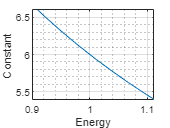

figure(1)
plot(E,Cs), grid on, grid minor
xlabel('Energy'); ylabel('Constant')
ylim([5.4 6.6])

So, we get from this plot, for value of 0.91 < E < 1.11 MeV of E, this constant's value lies within 10% of 6. Then the energy **range is 0.2 MeV**

(Ans)

Now, let's plot the values for 25% accuracy of the constant which ranges from 4.5 to 7.5. 

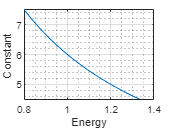

figure(2)
plot(E,Cs), grid on, grid minor
xlabel('Energy'); ylabel('Constant')
ylim([4.5 7.5])

So, the figure shows taht for value of approximately 0.8 < E < 1.34 MeV of E, this value lies within 25% of 6. The energy **range is 0.54 MeV**

(Ans)